# Measurements in calibration (aluminium) sample

**Author**: Abakumov Ivan, Martin Rühlmann

**Publication date**: 7th September 2019

**E-mail**: abakumov_ivan@mail.ru

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Part I: Radial measurements

## Upload measurements on Aluminium sample 

Data = zeros(110,10000);

for ii = 1:110
    filename = ['/remote/data/ivan/Ultrasonic_data/ALU_radial_calibration/tek' mynum2str(ii,4) 'CH2.csv'];
    data = read_csv_files(filename,15,10014);
    Data(ii,:) = data(:,2);
    tt = data(:,1);
end

Amplitude normalization

nData = Data; 
for i = 1:110
    nData(i,:) = Data(i,:)/max(Data(i,:)); 
end

Clip first arrival signal

cData = zeros(size(nData)); 

for i = 1:110
    trace = nData(i,:);
    [~,imax] = max(trace);
    ind = (imax-125):(imax+91);
    cData(i,ind) = nData(i,ind)-0.01; 
end

## Estimate timeshifts by cross-correlation of traces

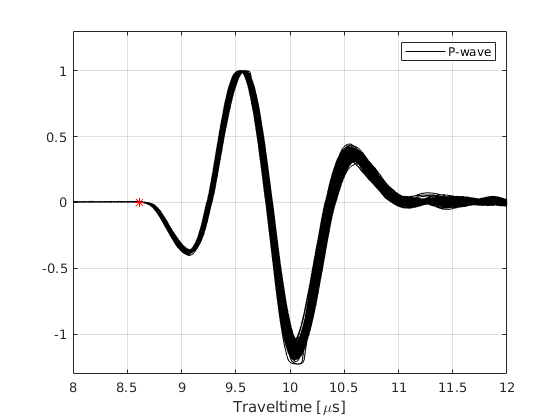

tP = 8.61e-6;  % traveltime of P wave in Al

figure(611)
plot(1e6*tt, nData','k');
hold on 
plot(1e6*tP, 0, 'r*');
axis([8, 12, -1.3 1.3])
xlabel('Traveltime [\mus]')
grid on
legend('P-wave')


dt = 1e-08

dt = 1.0000e-08

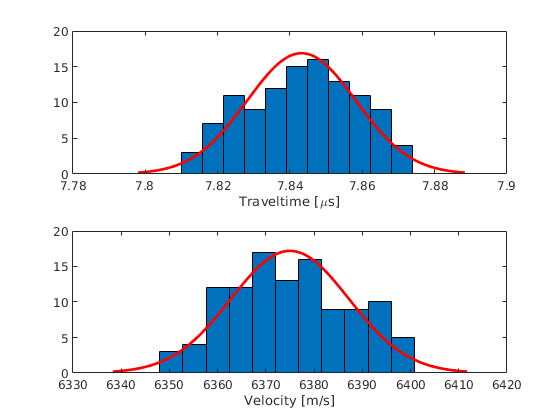

for i = 1:110
        trace1 = cData(1,:);
        trace2 = cData(i,:);
        [DT(i),  C(i)]  = mycorr(trace1, trace2, dt);
end
%[~,imax] = max(trace1);
%TT = DT + tt(imax);
%Tcor = 171.8*dt;
TT = DT + tP;
Tcor = 0.798e-6; 
TT = TT - Tcor;
V = 0.050./(TT);

figure(2)
subplot(2,1,1); histfit(TT*1e6',11)
xlabel('Traveltime [\mus]')
subplot(2,1,2); histfit(V',11)
xlabel('Velocity [m/s]')


fitdist(TT','Normal')

ans =   NormalDistribution

  Normal distribution
       mu = 7.84319e-06   [7.84034e-06, 7.84604e-06]
    sigma = 1.50611e-08   [1.32997e-08, 1.73646e-08]


fitdist(V','Normal')

ans =   NormalDistribution

  Normal distribution
       mu = 6374.98   [6372.67, 6377.29]
    sigma = 12.2442   [10.8122, 14.1168]


## Part II: axial measurements

$T_{Al}$ = 18.52 $\mu$s for P-waves in axial direction

$T_{Al}$ = 37.95 $\mu$s for S-waves in axial direction

clear all; 

tP = 18.52e-6; 
tS = 37.95e-6; 


Data = zeros(100,10000);
Wave_type = zeros(1,100); 
Wave_type([1:10, 21:30, 41:50, 61:70, 81:90]) = 1; 
Pressure = zeros(1,100); 
Presure(1:20) = 0; 
Presure(21:40) = 5; 
Presure(41:60) = 10; 
Presure(61:80) = 20; 
Presure(81:100) = 30; 

for ii = 1:100
    filename = ['/remote/data/ivan/Ultrasonic_data/ALU_axial_calibration/org/tek' mynum2str(ii,4) 'CH2.csv'];
    data = read_csv_files(filename,15,10014);
    Data(ii,:) = data(:,2);
    tt = data(:,1);
end

PData = Data(Wave_type==1,:); 
SData = Data(Wave_type==0,:); 


Amplitude normalization of P-waves

nPData = PData; 
for i = 1:50
    nPData(i,:) = PData(i,:)/max(PData(i,:)); 
end

Amplitude normalization of S-waves

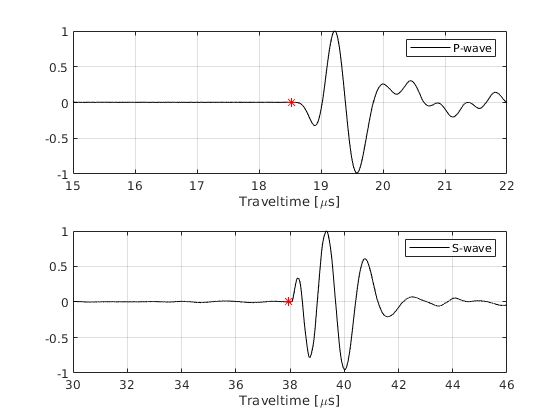

nSData = SData; 
for i = 1:50
    nSData(i,:) = SData(i,:)/max(abs(SData(i,:))); 
end

figure(3)
subplot(2,1,1)
plot(1e6*tt, nPData(10,:),'k')
hold on
plot(1e6*tP, 0, 'r*')
axis([15, 22, -1 1])
xlabel('Traveltime [\mus]')
legend('P-wave')
grid on
subplot(2,1,2)
plot(1e6*tt, nSData(10,:),'k')
hold on
plot(1e6*tS, 0, 'r*')
axis([30, 46, -1 1])
xlabel('Traveltime [\mus]')
legend('S-wave')
grid on